% Problem dimensions
dims = [10, 20, 50, 100, 150, 200, 250, 300, 350, 400, 450, 500];
results_IRWA_scaling = zeros(size(dims));
results_ADMM = zeros(size(dims));
results_osqp = zeros(size(dims));
result_normalized_IRWA = zeros(size(dims));
result_normalized_ADMM = zeros(size(dims));


% Loop over dimensions
for i = 1:length(dims)
    n = dims(i);
    % Generate random QP problem
    [H, g, A1, A2, b1, b2] = generate_random_qp(n, floor(n/4), floor(n/6));
    
    % IRWA QP scaling method
    y = IRWA_QP_scaling(A1, A2, -b1, -b2, g, H);
    results_IRWA_scaling(i) = y' * H * y / 2 + g' * y;

    % ADMM method
    y = ADMM_QP(A1, A2, -b1, -b2, g, H);
    results_ADMM(i) = y' * H * y / 2 + g' * y;

    % OSQP method
    [A, l, u] = standard_constraints(A2, b2, A1, b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    results = m.solve();
    x_osqp = results.x;
    results_osqp(i) = x_osqp' * H * x_osqp / 2 + g' * x_osqp;

    % Normalized deviation
    result_normalized_IRWA(i) = 100 * (results_IRWA_scaling(i) - results_osqp(i)) / results_osqp(i);
    result_normalized_ADMM(i) = 100 * (results_ADMM(i) - results_osqp(i)) / results_osqp(i);
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 10, constraints m = 3
          nnz(P) + nnz(A) = 85
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.1225e-01   1.23e+00   1.08e+03   1.00e-01   1.28e-04s
  50  -2.0361e-01   1.86e-09   1.50e-08   1.00e-01   2.83e-04s

status:               solved
number of iterations: 50
optimal objective:    -0.2036
run time:             4.23e-04s
optimal rho estimate: 5.78e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -3.4376e-01   1.13e+00   1.73e+03   1.00e-01   1.74e-04s
  50  -8.1586e-01   1.83e-09   2.25e-08   1.00e-01   3.70e-04s

status:               solved
number of iterations: 50
optimal objective:    -0.8159
run time:             5.31e-04s
optimal rho estimate: 4.30e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -1.1566e+00   2.46e+00   5.31e+03   1.00e-01   3.40e-04s
  50   5.3436e+00   2.45e-09   7.13e-08   1.00e-01   6.33e-04s

status:               solved
number of iterations: 50
optimal objective:    5.3436
run time:             8.68e-04s
optimal rho estimate: 3.47e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 41
          nnz(P) + nnz(A) = 9150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -9.8089e-01   2.12e+00   1.87e+04   1.00e-01   2.11e-03s
  50   8.5096e+00   1.53e-07   2.45e-07   1.63e-02   3.64e-03s

status:               solved
number of iterations: 50
optimal objective:    8.5096
run time:             3.94e-03s
optimal rho estimate: 2.90e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 150, constraints m = 62
          nnz(P) + nnz(A) = 20625
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.4709e-01   2.85e+00   3.22e+04   1.00e-01   6.41e-03s
  75   1.9103e+01   7.13e-09   6.91e-07   1.00e-01   1.10e-02s

status:               solved
number of iterations: 75
optimal objective:    19.1033
run time:             1.21e-02s
optimal rho estimate: 2.25e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 83
          nnz(P) + nnz(A) = 36700
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.6471e-01   2.79e+00   4.46e+04   1.00e-01   9.58e-03s
  50   1.5190e+01   1.76e-08   5.72e-07   1.47e-02   2.06e-02s

status:               solved
number of iterations: 50
optimal objective:    15.1902
run time:             2.11e-02s
optimal rho estimate: 5.99e-03



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 250, constraints m = 103
          nnz(P) + nnz(A) = 57125
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.7569e-01   2.21e+00   6.73e+04   1.00e-01   1.58e-02s
 100   2.5598e+01   3.19e-08   7.03e-06   1.00e-01   2.71e-02s

status:               solved
number of iterations: 100
optimal objective:    25.5981
run time:             2.75e-02s
optimal rho estimate: 1.83e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 125
          nnz(P) + nnz(A) = 82650
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.5997e-01   2.62e+00   9.63e+04   1.00e-01   3.01e-02s
  75   2.7333e+01   1.23e-08   6.17e-09   9.12e-03   6.08e-02s

status:               solved
number of iterations: 75
optimal objective:    27.3334
run time:             6.13e-02s
optimal rho estimate: 3.15e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 350, constraints m = 145
          nnz(P) + nnz(A) = 112175
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.0437e-01   2.31e+00   1.03e+05   1.00e-01   4.84e-02s
 125   3.0376e+01   2.82e-09   1.42e-08   1.16e-02   1.17e-01s

status:               solved
number of iterations: 125
optimal objective:    30.3757
run time:             1.18e-01s
optimal rho estimate: 1.44e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 166
          nnz(P) + nnz(A) = 146600
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.4518e-01   3.09e+00   1.21e+05   1.00e-01   6.45e-02s
 100   3.0845e+01   1.56e-10   1.56e-10   1.06e-02   1.37e-01s

status:               solved
number of iterations: 100
optimal objective:    30.8451
run time:             1.38e-01s
optimal rho estimate: 2.62e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 450, constraints m = 187
          nnz(P) + nnz(A) = 185625
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.3048e-01   3.15e+00   1.48e+05   1.00e-01   9.97e-02s
 100   3.7644e+01   3.36e-08   3.25e-08   7.73e-03   2.00e-01s

status:               solved
number of iterations: 100
optimal objective:    37.6437
run time:             2.13e-01s
optimal rho estimate: 1.95e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 208
          nnz(P) + nnz(A) = 229250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.2520e-01   2.73e+00   2.12e+05   1.00e-01   1.15e-01s
 100   2.7062e+01   1.15e-08   1.03e-08   7.52e-03   2.42e-01s

status:               solved
number of iterations: 100
optimal objective:    27.0622
run time:             2.55e-01s
optimal rho estimate: 1.89e-02



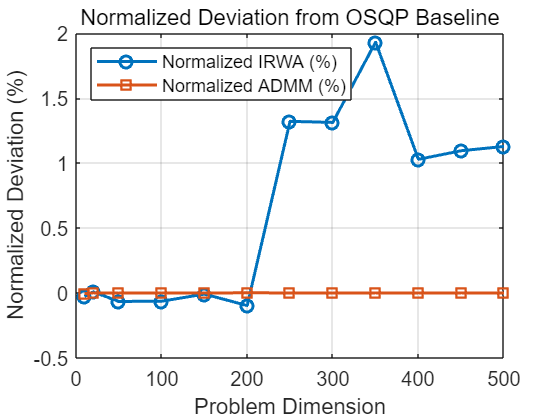


% Plot results
result_normalized_IRWA = result_normalized_IRWA .* results_osqp ./ results_IRWA_scaling;
result_normalized_ADMM = result_normalized_ADMM .* results_osqp ./ results_ADMM;

figure;
plot(dims, result_normalized_IRWA, '-o', 'LineWidth', 1.5, 'DisplayName', 'Normalized IRWA (%)');
hold on;
plot(dims, result_normalized_ADMM, '-s', 'LineWidth', 1.5, 'DisplayName', 'Normalized ADMM (%)');
xlabel('Problem Dimension');
ylabel('Normalized Deviation (%)');
title('Normalized Deviation from OSQP Baseline');
legend('Location', 'northwest');
grid on;

% result_normalized_IRWA = result_normalized_IRWA .* results_osqp ./ results_IRWA_scaling;
% result_normalized_ADMM = result_normalized_ADMM .* results_osqp ./ results_ADMM;
% 
% figure;
% plot(dims, result_normalized_IRWA, '-o', 'LineWidth', 1.5, 'DisplayName', 'Normalized IRWA (%)');
% hold on;
% plot(dims, result_normalized_ADMM, '-s', 'LineWidth', 1.5, 'DisplayName', 'Normalized ADMM (%)');
% xlabel('Problem Dimension');
% ylabel('Normalized Deviation (%)');
% title('Normalized Deviation from OSQP Baseline');
% legend('Location', 'northwest');
% grid on;

function x = IRWA_QP_scaling(A1, A2, b1, b2, g, H)
    A = [A1; A2];
    b = [b1; b2];

    n = size(g, 1);
    m_eq = size(A1, 1);
    m_ineq = size(A2, 1);
    m = size(A, 1);
    epsilon = ones(m, 1);
    x = zeros(n, 1);
    gamma = 0;
    if n<=200
        eta = 0.99;
        M = 10;
    elseif n<1000
        eta = 0.9;
        M = 20;
    else 
        eta = 0.9;
        M = 100;
    end
    prim_tol = 1e-6;
    dual_tol = 1e-6;
    max_iter = 4000;

    scale_eq = 1 / norm(A1, 'fro');
    scale_ineq = 1 / norm(A2, 'fro');  
    scaling_matrix = diag([scale_eq * ones(m_eq, 1); scale_ineq * ones(m_ineq, 1)]);

    A_scaled = scaling_matrix * A;
    b_scaled = scaling_matrix * b;

    for k = 1:max_iter
        Eq = A1 * x;
        Ineq = A2 * x;
        w = [Eq + b1; (max(Ineq, -b2) + b2)];

        w_scaled = scaling_matrix * w;
        % w_scaled =(epsilon.^2 + w_scaled.^2).^(-0.5) + 1 ./ epsilon;
        w_scaled =max((epsilon.^2 + w_scaled.^2).^(-0.5) ,1 ./ epsilon);
        W = diag(w_scaled);

        v = scaling_matrix * [b1; max(-Ineq, b2)];

        H_tilde = H + A_scaled' * W * A_scaled;
        g_tilde = g + A_scaled' * W * v;
        x_next = lsqminnorm(H_tilde, -g_tilde);

        q = A_scaled * (x_next - x);
        r = scaling_matrix * ((1 - v) .* (A_scaled * x + b_scaled));

        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta;
        end
        primal =norm(x_next - x,inf);
        er =norm(epsilon,inf);

        if primal <= prim_tol && er <= dual_tol
            x = x_next;
            break;
        end
        % x'*H*x/2+g'*x
        x = x_next;
    end
end

function x = ADMM_QP(A1,A2,b1,b2, q, P)
    % Import necessary utility functions
    [A,l,u] = standard_constraints(A2,-b2,A1,-b1);
    sigma = 1e-6;
    alpha = 1.6;
    n = size(P, 1);
    m = size(A, 1);
    x = zeros(n,1);
    y = zeros(m,1);
    z = zeros(m,1);
    rho = 0.1;
    prim_tol = 1e-4;
    dual_tol = 1e-6;
    max_iter = 100;
    if n<100
        inner_loop = 50;
    elseif n<1000
        inner_loop  = 200;
    else
        inner_loop = 500;
    end
    
    function rho_estimate = compute_rho()
        RHO_MIN = 1e-06;
        RHO_MAX=1;
        DIVISION_TOL = 1e-20;
        prim_res_norm = norm(z,1);
        temp_res_norm = norm(A*x,1); 
        prim_res_norm = max(prim_res_norm, temp_res_norm);
        prim_res = prim_res/(prim_res_norm + DIVISION_TOL);
        
        dual_res_norm = norm(q,1);
        temp_res_norm = norm(A'*y,1);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        temp_res_norm = norm(P*x,1);
        dual_res_norm = max(dual_res_norm, temp_res_norm);
        dual_res = dual_res/(dual_res_norm + DIVISION_TOL);
    
        rho_estimate = norm(rho * sqrt(prim_res / dual_res),1);
        rho_estimate = min(max(rho_estimate, RHO_MIN), RHO_MAX);
    end
    for i = 1: max_iter
        x_prev = x;
        for j = 1:inner_loop
            M = P + sigma * eye(n) + rho * (A'* A);
            b =  sigma* x - q + A'*(rho*z - y );
            x_tilde = conjgrad(M,b);
            z_tidle = A*x_tilde;
            x_next = alpha * x_tilde + (1 - alpha) * x;
            z_next = Pc(alpha * z_tidle + (1 - alpha) * z + 1 / rho * y, l, u);
            y = y + rho * (alpha * z_tidle + (1 - alpha) * z - z_next);
            z = z_next;
            prim_res = A*x-z;
            dual_res = P * x_next + q + A' * y;
    
            if norm(prim_res) <= prim_tol && norm(dual_res) <= dual_tol
                x = x_next;
                break;
            end
            if norm(x-x_next,2)<1e-5
                break
            end
            x_prev = x;
            x = x_next;
        end
        if norm(x-x_prev,2)<1e-5
            break
        end
        rho = compute_rho();
    end
end